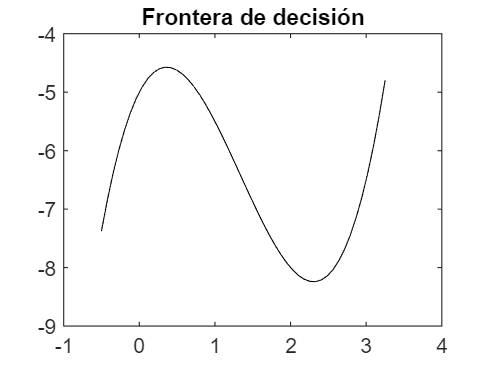

N = 100; % Número de muestras
x = linspace(-0.5,3.25,N/2);
y = 1*x.^3-4*x.^2+2.5*x-5;
figure
plot(x,y,'k')
title('Frontera de decisión')

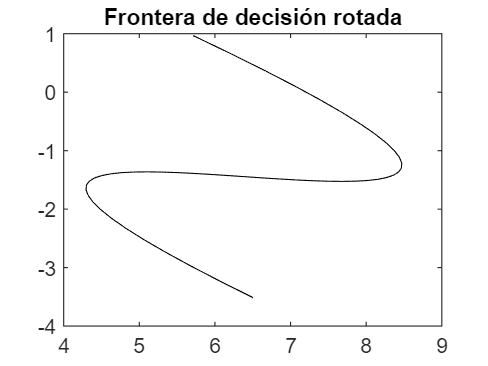



N = 100; % Número de muestras
alpha = 65.495;     %angulo a rotar
x = linspace(-0.5,3.25,N/2);
y = 1*x.^3-4*x.^2+2.5*x-5;
P = [x; y];      %vector que contiene punto a rotar
% Matriz a usar
Mz = [cosd(alpha), -sind(alpha);...
      sind(alpha), cosd(alpha)];
R = Mz*P;   
figure
plot(R(1,:),R(2,:),'k');
title('Frontera de decisión rotada')

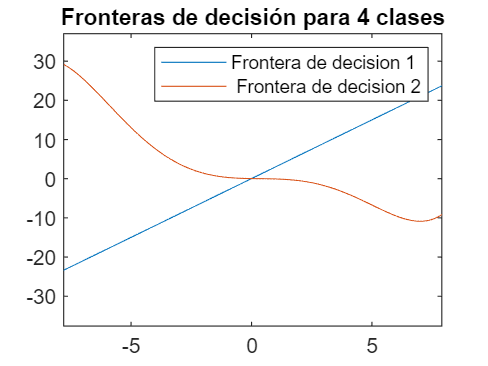


n=1000;
x = linspace(-8,8,n/4);
y1 = -0.00005*x.^3-0.0001*x.^2+3*x+0.03;
y2 = 0.001*x.^5+0.001*x.^4-0.1*x.^3+0.1*x.^2-0.1*x+0.03;
figure
plot(x,y1,x,y2)
title('Fronteras de decisión para 4 clases')
legend('Frontera de decision 1',' Frontera de decision 2')
xlim([-7.8 7.9])
ylim([-37.6 37.0])